Process idettification data

clear all;
filename='identification_temperature_1_1.csv'

filename = 'identification_temperature_1_1.csv'

Tp=0.2;
[model.timeUTC model.sp model.pv model.cv model.orifice model.resistance model.ds3] = csvimport(filename, 'columns', {'UTC Time','SP', 'PV', 'CV', 'DS1', 'DS2', 'DS3'});
model.time(1)=0;
for i=2:length(model.timeUTC)
   model.time(i,1)=Tp*(i-1);
end

model1_ident=model;

clear model;

filename='identification_temperature_1_2.csv'

filename = 'identification_temperature_1_2.csv'

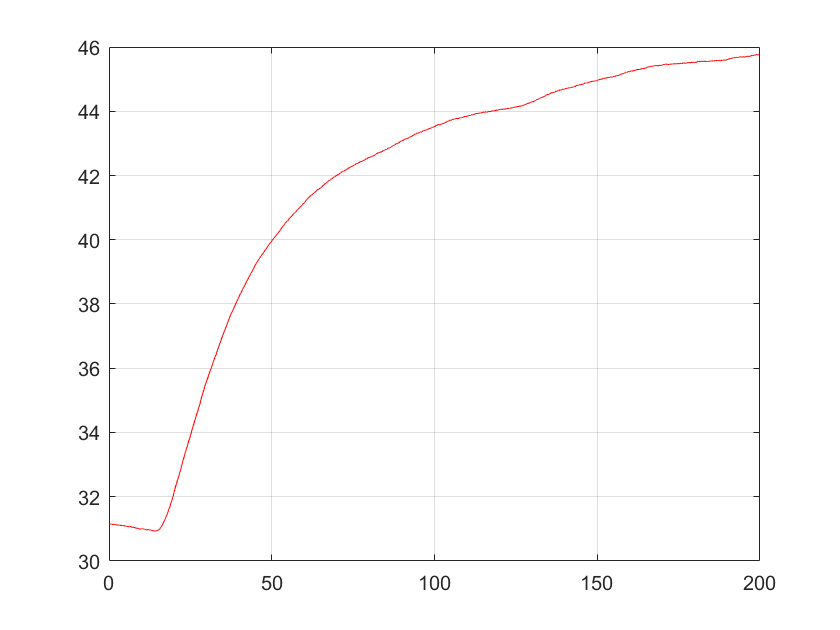

[model.timeUTC model.sp model.pv model.cv model.orifice model.resistance model.ds3] = csvimport(filename, 'columns', {'UTC Time','SP', 'PV', 'CV', 'DS1', 'DS2', 'DS3'});
model.time(1)=0;
for i=2:length(model.timeUTC)
   model.time(i,1)=Tp*(i-1);
end;

model2_ident=model;
pom=model1_ident.time(length(model1_ident.time))+0.2;
for i=1:length(model2_ident.time)
   model2_ident.time(i)=pom+model2_ident.time(i);
end

plot(model1_ident.time,model1_ident.pv,'r');
hold on;
grid on;
plot(model1_ident.time,model1_ident.pv,'r');
hold off;

Temperature - resistance disturbance

clear model;

filename='identification_disturbance_resistance.csv'

filename = 'identification_disturbance_resistance.csv'

Tp=0.2;
[model.timeUTC model.sp model.pv model.cv model.orifice model.resistance model.ds3] = csvimport(filename, 'columns', {'UTC Time','SP', 'PV', 'CV', 'DS1', 'DS2', 'DS3'});
model.time(1)=0;
for i=2:length(model.timeUTC)
   model.time(i,1)=Tp*(i-1);
end

model_temp_res=model;

subplot(2,1,1)
plot(model_temp_res.time,model_temp_res.pv,'red');
grid on;
xlabel('time[s]')
ylabel('temperature[%]')
subplot(2,1,2)
plot(model_temp_res.time,model_temp_res.resistance,'blue');
grid on;
xlabel('time[s]')
ylabel('control[%]')


Temperature - orifice disturbance

clear model;

filename='identification_disturbance_orifice.csv'

filename = 'identification_disturbance_orifice.csv'

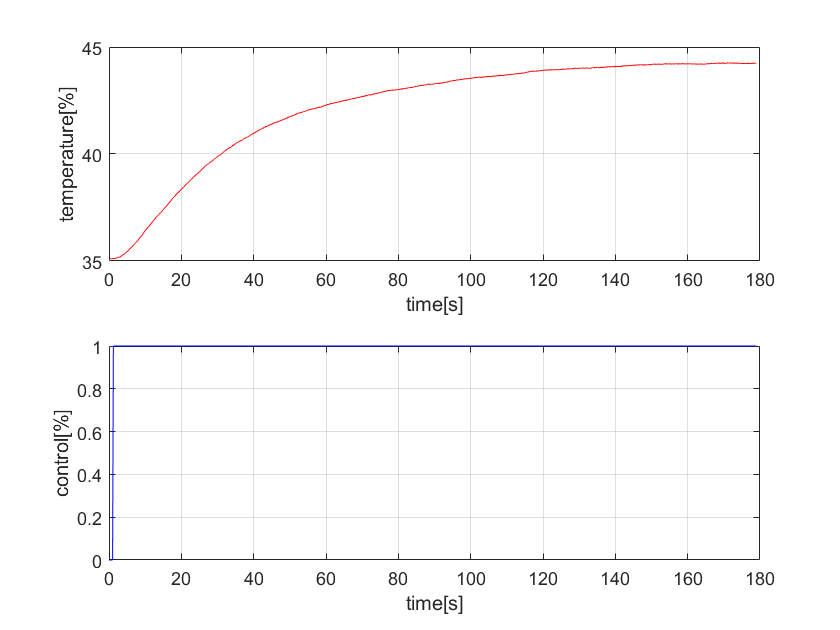

Tp=0.2;
[model.timeUTC model.sp model.pv model.cv model.orifice model.resistance model.ds3] = csvimport(filename, 'columns', {'UTC Time','SP', 'PV', 'CV', 'DS1', 'DS2', 'DS3'});
model.time(1)=0;
for i=2:length(model.timeUTC)
   model.time(i,1)=Tp*(i-1);
end

model_temp_ori=model;

plot(model_temp_ori.time,model_temp_ori.pv,'r');
grid on;

subplot(2,1,1)
plot(model_temp_ori.time,model_temp_ori.pv,'red');
grid on;
xlabel('time[s]')
ylabel('temperature[%]')
subplot(2,1,2)
plot(model_temp_ori.time,model_temp_ori.orifice,'blue');
grid on;
xlabel('time[s]')
ylabel('control[%]')